# Práctica 1: Complejidad

En esta práctica se analiza la complejidad de un algoritmo.

**Borrón y cuenta nueva!!**

clc, clear, close all

## 1. Crecimiento polinomial y crecimiento exponencial

Vamos a representar la gráficas de diversas funciones para analizar si se tiene un crecimiento polinomial o exponencial. En esencia se tiene la relación


$$\lim_{n\rightarrow +\infty} \frac{P(n)}{a^n}=0;  \quad   a>1$$


que indica que cualquier crecimiento exponencial es más rápido que el crecimiento de cualquier polinomio $P\left(n\right)$ independientemente del grado que tenga.

### Visualización usando escala logarítmica

Vamos a representar los polinomios $n,n^{\;2,} ,n^{\;3} ,\ldotp \ldotp \ldotp ,n^{10}$ y las funciones exponenciales $2^{\;n,} ,3^{n,} ,\ldotp \ldotp \ldotp ,{10}^{\;n\;}$para comparar su crecimiento

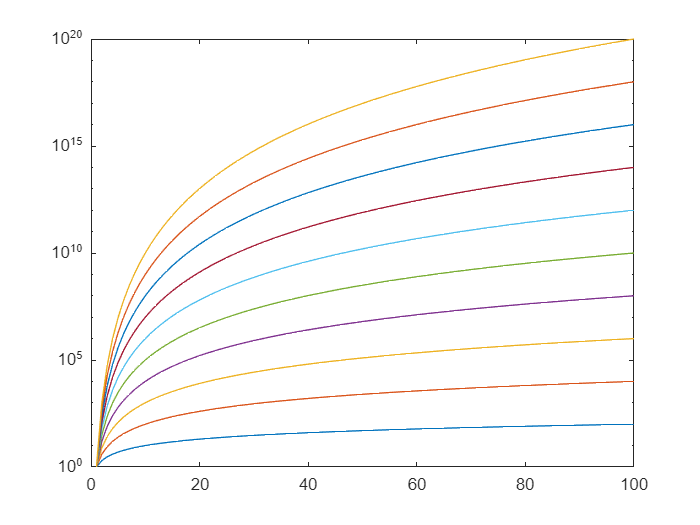

% Generación de un vector conteniendo los datos
n=1:100; % n es el vector [1,2,3,...,100]
% Cálculo de las imagenes
figure(1)
for grado=1:10
    y=n.^grado;     % cálculo de imagenes del polinomio
    semilogy(n,y)   % crea un gráfico donde la Y toma escala logarítmica
    hold on         % dibuja las gráficas en la misma figura
end

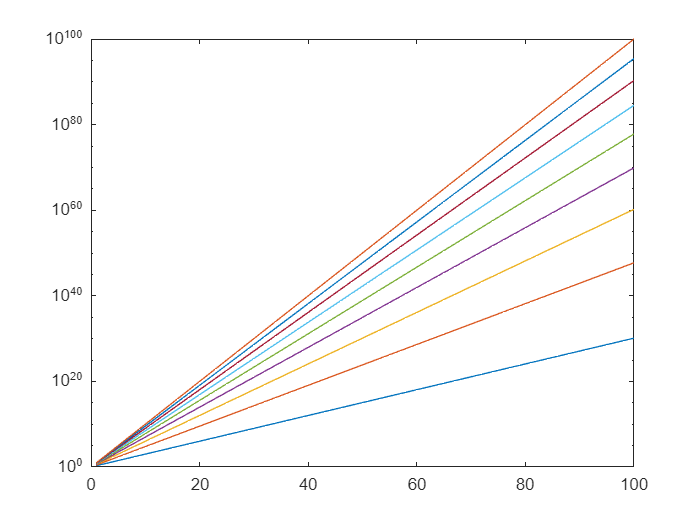

% funciones exponenciales
figure(2)
for base=2:10
    y=base.^n;      % cálculo de imagenes de la función exponciales
    semilogy(n,y)   % crea un gráfico donde la Y toma escala logarítmica
    hold on         % dibuja las gráficas en la misma figura
end

La escala logarítmica en el eje Y equivale a tomar $\log \left(P\left(n\right)\right)$y toma un aspecto cóncavo mientras que las funciones exponenciales $\log a^n= \log a \cdot n$ es una recta. Concluyendo, un aspecto de las gráficas tipo recta o mostrando una función  convexa es un crecimiento exponencial y un aspecto que revela una función cóncava está aosicado a un crecimiento "polinomial"

### Ejercicio

- ¿La función factorial tiene un crecimiento exponecial o polinomial?

## Completar con el código correspondiente

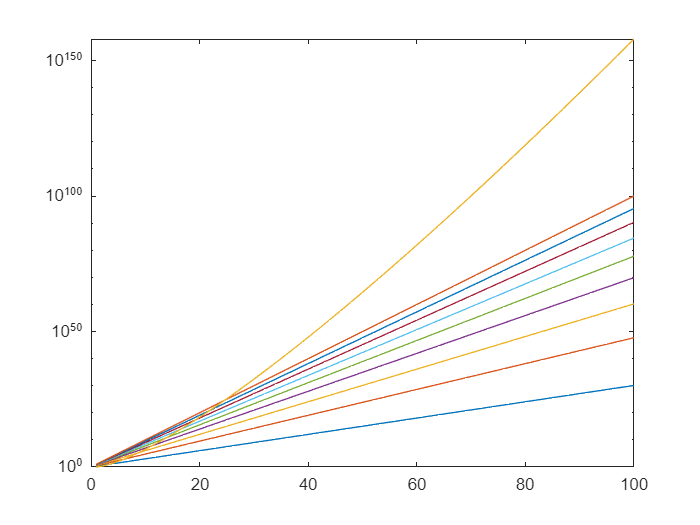

n=1:100; % n vector 1-100
y=factorial(n); % y vector con el resultado del factorial de cada número
semilogy(n,y); % representación de los dos vecotres

% Es un crecimiento exponencial el aspecto de la gráfica tipo función convexa


- Si Dios duplicase cada día el número de átomos de hidrógeno del día anterior y suponiendo que el primer día había dos átomos de hidrógeno ¿Cuantos días hubiera tardado en crear el Universo (contiene $4*{10}^{79} \;$átomos de hidrógeno). Sabiendo que la Tierra la creó en siete días, ¿Cuantos átomos de hidrógeno tendría la Tierra?

% Completar con el código correspondiente
% Primera forma de hacerlo
log2(4*10^79)

ans = 264.4323

% Segunda forma de hacerlo
dias = 1;
while 2^dias < 4*10^79
    dias = dias + 1;
end
disp(dias)

   265



- Analizar gáficamente si la expansión del COVID-19 tiene un crecimiento exponencial. Considerar la siguiente web [WEB COVID-19 GRUPO MAT](https://covid19.esi.uclm.es)

## 2. Clases de complejidad

- Se dice que un **algoritmo **tiene un tiempo de ejecución **polinomial ** si el número de operaciones máximo que realiza para resolver un problema está actoado por un polinomio en el tamaño del problema. Por ejemplo si queremos ordenar un vector mediante un algoritmo A y podemos acotar el número de operaciones que realiza el algoritmo A por un polinomio en función de la longitud del vector n, diremos que el algoritmo A es polinomial.

- Se dice que un problema está en la **clase de complejidad P ** si existe un algoritmo para resolver el problema que tiene un tiempo de ejecución polinomial. Si no se conoce ningún algoritmo que lo resuelva en tiempo polinomial se dice que el problema está en la **clase de complejidad NP.**

- Dentro de los problema NP existen un subconjunto de problemas llamados **NP-completos. **Si uno de estos problemas tuvieran un algoritmo de resolución polinomial entonces todos los problemas de la clase NP también tendrían un algoritmo polinomial y en dicho caso **P=NP. ** El [Clay Mathematics Institute](https://es.wikipedia.org/wiki/Clay_Mathematics_Institute) ofrece un millón de dólares a quien sea capaz de responder a esa pregunta. 

### **Ejemplo 1: Sucesión de Fibonacci **

La sucesión de Fibonacci se define tomando los dos primeros términos $y_1=1,y_2=1$ y los siguientes se generan mediante la expresión:

                                                                                    
$$y_n=y_{n-1}+y_{n-2};  \ \ \ n \ge 2$$


Si nos planteamos el problema de calcular el término n-ésimo de esta sucesión podemos considerar dos algoritmos. El primero es generar todos los términos empezando desde el primero, segundo en adelante. Implementar este procedimiento  en una  función que se denomine  FiobonacciA() y calcular los términos tercero y décimo.

% Implementar la función FibonacciA()

% Calcular el tercer término de la sucesión de Fibonacci
FibonacciA(3);

     2



% Cáclcular el décimo término de la sucesión de Fibonacci
FibonacciA(10);

    55



Podemos calcular el término de forma alternativa. Podemos empezar en el término n-esimo, este nos llevará a calcular los dos anteriores, a su vez cada uno de ellos a dos anteriores y así sucesivamente. Esta es una definición **recursiva. **Codifica este procedimiento y denominalo FibonacciB() . Vuelve a calcular los términos tercero y décimo con la misma función.

% % Implementar la función FibonacciB()

% Cálculo del tercer término de la sucesión de Fibonacci con la definición recursiva
FibonacciB(3);

     1

     1

     2



% Cálculo del décimo término de la sucesión de Fibonacci con la definición
% recursiva
FibonacciB(10);

     1

     1

     2

     1

     3

     1

     1

     2

     5

     1

     1

     2

     1

     3

     8

     1

     1

     2

     1

     3

     1

     1

     2

     5

    13

     1

     1

     2

     1

     3

     1

     1

     2

     5

     1

     1

     2

     1

     3

     8

    21

     1

     1

     2

     1

     3

     1

     1

     2

     5

     1

     1

     2

     1

     3

     8

     1

     1

     2

     1

     3

     1

     1

     2

     5

    13

    34

     1

     1

     2

     1

     3

     1

     1

     2

     5

     1

     1

     2

     1

     3

     8

     1

     1

     2

     1

     3

     1

     1

     2

     5

    13

     1

     1

     2

     1

     3

     1

     1

     2

     5

     1

     1

     2

     1

     3

     8

    21

    55



### Ejercicios. Tiempo CPU

La instrucción tic inicializa el contador de tiempo y cada vez que se ejecuta la instrucción toc se calcula el tiempo de CPU transcurrido entre la llamada tic y la siguiente llamada toc Estas dos sentencias nos permiten calcular el tiempo de ejecución de un algoritmo. Se pide que se mida el tiempo de ejecución de los algoritmos FibonacciA() y FibonacciB() para calcular cada uno de los primeros cincuenta términos de la sucesión.

% Cálculo del tiempo de ejecución del algoritmo FibonacciA()
tic;
formatSpec = 'n = %i z_n= %i CPU= %5.3f \n';
for n=1:50
    t_inicio=toc;
    fprintf(formatSpec,n, FibonacciA(n), (toc-t_inicio))
    t_inicio=toc;
end

     1

n = 1 z_n= 1 CPU= 0.001 
     1

n = 2 z_n= 1 CPU= 0.000 
     2

n = 3 z_n= 2 CPU= 0.000 
     3

n = 4 z_n= 3 CPU= 0.000 
     5

n = 5 z_n= 5 CPU= 0.000 
     8

n = 6 z_n= 8 CPU= 0.000 
    13

n = 7 z_n= 13 CPU= 0.000 
    21

n = 8 z_n= 21 CPU= 0.000 
    34

n = 9 z_n= 34 CPU= 0.000 
    55

n = 10 z_n= 55 CPU= 0.000 
    89

n = 11 z_n= 89 CPU= 0.000 
   144

n = 12 z_n= 144 CPU= 0.000 
   233

n = 13 z_n= 233 CPU= 0.000 
   377

n = 14 z_n= 377 CPU= 0.000 
   610

n = 15 z_n= 610 CPU= 0.000 
   987

n = 16 z_n= 987 CPU= 0.000 
        1597

n = 17 z_n= 1597 CPU= 0.000 
        2584

n = 18 z_n= 2584 CPU= 0.000 
        4181

n = 19 z_n= 4181 CPU= 0.000 
        6765

n = 20 z_n= 6765 CPU= 0.000 
       10946

n = 21 z_n= 10946 CPU= 0.000 
       17711

n = 22 z_n= 17711 CPU= 0.000 
       28657

n = 23 z_n= 28657 CPU= 0.000 
       46368

n = 24 z_n= 46368 CPU= 0.000 
       75025

n = 25 z_n= 75025 CPU= 0.000 
      121393

n = 26 z_n= 121393 CPU= 0.000 
      196418


% Cálculo del tiempo de ejecucción del algoritmo FibonacciB()
tic;
formatSpec = 'n = %i z_n= %i CPU= %5.3f \n';
for n=1:50
    t_inicio=toc;
    fprintf(formatSpec,n, FibonacciB(n), (toc-t_inicio))
    t_inicio=toc;
end

     1

n = 1 z_n= 1 CPU= 0.000 
     1

n = 2 z_n= 1 CPU= 0.000 
     1

     1

     2

n = 3 z_n= 2 CPU= 0.000 
     1

     1

     2

     1

     3

n = 4 z_n= 3 CPU= 0.000 
     1

     1

     2

     1

     3

     1

     1

     2

     5

n = 5 z_n= 5 CPU= 0.001 
     1

     1

     2

     1

     3

     1

     1

     2

     5

     1

     1

     2

     1

     3

     8

n = 6 z_n= 8 CPU= 0.001 
     1

     1

     2

     1

     3

     1

     1

     2

     5

     1

     1

     2

     1

     3

     8

     1

     1

     2

     1

     3

     1

     1

     2

     5

    13

n = 7 z_n= 13 CPU= 0.002 
     1

     1

     2

     1

     3

     1

     1

     2

     5

     1

     1

     2

     1

     3

     8

     1

     1

     2

     1

     3

     1

     1

     2

     5

    13

     1

     1

     2

     1

     3

     1

     1

     2

     5

     1

     1

     2

     1

     3

     8

    21

n = 8 z_n= 21 CPU= 0.003

Entonces se tiene que el algoritmo FibonacciA() corre en un tiempo polinomial (lineal) y el FibonacciB() en un tiempo exponencial, por lo que el problema de calcular el término n-esimo de la sucesión de Fibonacci es un problema de la clase P, porque hemos encontrardo un algoritmo (FibonacciA()) que corre en tiempo polinomial. Los problemas de la clase NP son aquellos que solo se disponen, por el momento, de algoritmos que no corren en un tiempo polinomial.

### **Ejemplo 2: Vacunación COVID-19 **

Considérese que se desea vacunar contra el COVID-19 a una fracción p de una población de n personas. Supóngase que se tiene un mapa/grafo de relaciones entre la población como el que se muestra a continuación:

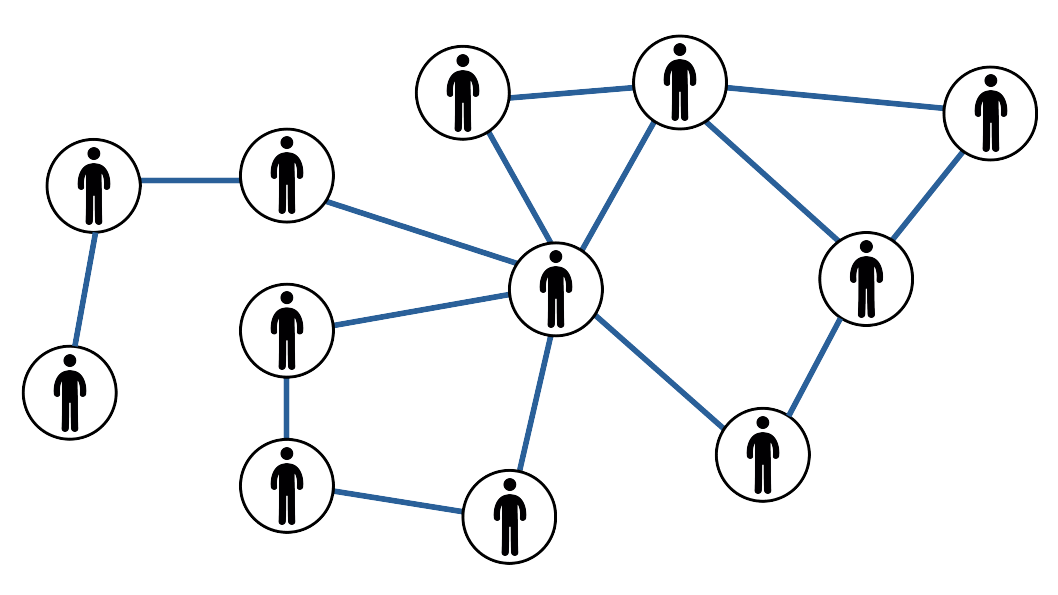

Supóngase que se vacuna a dos individuos (sombreados en amarillo). Observar que con esta elección de los individuos a vacunar se elimina 4 vias de transmisión de la infección.

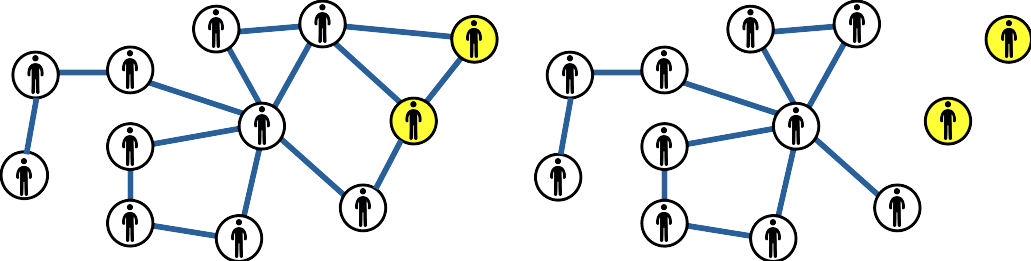

Si consideramos que vacunamos a los dos individuos siguientes, las líneas de transmisión eliminadas son ahora 9.

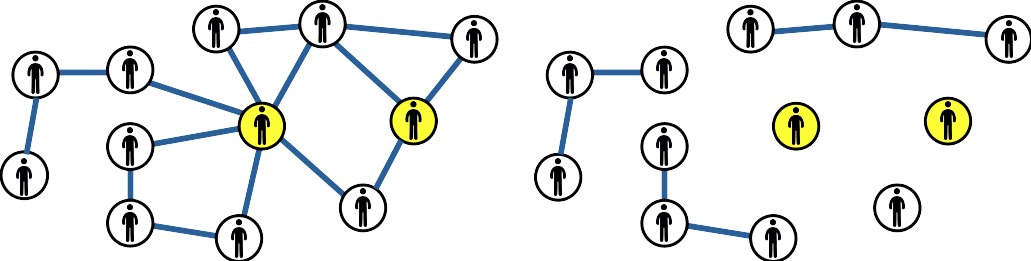

Nos planteamos el problema 

**                    MAXIMIZAR: **Número de lineas de transmisión eliminadas

**                    SUJETO A:    **Número de pacientes vacunados =k

### Ejercicio. ¿Más máquina o mejores algoritmos?

Considérese el algoritmo ** A= "fuerza bruta"** que genera todas las soluciones posibles del problema y encuentra la solución del problema evaluándo todas sus soluciones factibles

- Si consideramos que evaluar una solución es una operación. Asuminedo que disponemos de 30 vacunas, ¿cuántas operaciones realiza el algoritmo para poblaciones de entre 30 y 50 personas? instrucción en MATLAB ***nchoosek***

- Sea n el tamaño de la población y k el número de personas vacunadas. ¿Es un algorimo polinomial o no polinomial en el tamaño de la población? 

% Completar con el código correspondiente
% 12 Personas 2 vacunas 66 maneras de vacunar
nchoosek(12,2)
for n=30:50
    y(n-29)=nchoosek(n,30);
end
semilogy(30:50,y);
% Es exponencial

- Suponiendo una situación de k=40 vacunas y una población de n=150 personas. Si se dispone de un ordenador que realiza 1000000 operaciones por segundo. ¿Se podría resolver el anterior problema en un día? ¿en un mes?¿en un año? 

%% Completar con el código correspondiente
operaciones=nchoosek(150,40)

operaciones = 4.4089e+36

% Operaciones en un dia
ope_1dia = 1000000*24*60*60;
ope_1dia > operaciones

ans = logical
   0


% Operaciones en un mes
ope_1mes = 1000000*24*60*60*30;
% Comprobación
ope_1mes > operaciones

ans = logical
   0


% Operaciones en un año
ope_1anio = 1000000*24*60*60*365;
% Comprobación
ope_1anio > operaciones

ans = logical
   0


- ¿Cual es el problema máximo (n) que puede resolver este ordenador en un año?

%% Completar con el código correspondiente
% Empezamos en 40
n = 40;
k = 40;
% Al ser siempre las mismas vacunas vamos aumentando el numero de personas
% hasta que las operaciones sean superiores a las anuales.
while (nchoosek(n,k)<ope_1anio)
    n = n+1;
end

n=n-1; % Restamos 1 por el bucle while
disp(n);

    61



- Si hubiera un cambio disruptivo e la tecnología y se pudiera construir un ordenador 1000 veces más rápido que el anterior ¿Cuál sería hoara el tamaño máximo que se pudiera resolver en un días, mes o año? 

%% Completar con el código correspondiente
operaciones=nchoosek(150,40)
% Operaciones en un dia
ope_1dia = 1000000*24*60*60 * 1000;
ope_1dia > operaciones
% Operaciones en un mes

operaciones = 4.4089e+36

ope_1mes = 1000000*24*60*60*30 * 1000;
% Comprobación
ope_1mes > operaciones

ans = logical
   0


% Operaciones en un año
ope_1anio = 1000000*24*60*60*365 * 1000;
% Comprobación
ope_1anio > operaciones

ans = logical
   0


- Repetir el anterior apartado pero con 1000000 veces más rápido

%% Completar con el código correspondiente
operaciones=nchoosek(150,40)
% Operaciones en un dia
ope_1dia = 1000000*24*60*60 * 1000 * 1000;

ans = logical
   0


ope_1dia > operaciones
% Operaciones en un mes
ope_1mes = 1000000*24*60*60*30 * 1000 * 1000;
% Comprobación
ope_1mes > operaciones
% Operaciones en un año
ope_1anio = 1000000*24*60*60*365 * 1000 * 1000;
% Comprobación
ope_1anio > operaciones

Este es un problema de la clase P porque el único algoritmo que conocemos (fuerza bruta)  tiene un tiempo de ejecución polinomial (ver la gráfica inicial). Los números anteriores, incluso para este problema de la clase P, prueban que es irresoluble para tamaños reales (millones de personas y vacuna). Esto motiva la necesidad de los **algoritmos heurísticos **para encontrar soluciones "buenas" del problema en un tiempo asumible en el contexto del problema.